Cathy Zhuang

BIOL 450 Dr. Berman

16 April 2022

# Assignment 10: Dimensionality Reduction

## Part 1

#### Question A

Given that the volume of a hypersphere is  $\frac{\pi^{\frac{d}{2}} R^d }{\left(\frac{d}{2}\right)!}$  and the width of the peel is $\epsilon$, 

then the volume of the pulpy center (i.e. the volume of the sphere without the peel)  is given by:


$$\frac{\pi^{\frac{d}{2}} {\left(R-\epsilon \right)}^d }{\left(\frac{d}{2}\right)!}$$


and the volume of the peel is the volume of the hypersphere subtracted by the volume of the pulpy center, as follows:

$\frac{\pi^{\frac{d}{2}} R^d }{\left(\frac{d}{2}\right)!}-\frac{\pi^{\frac{d}{2}} {\left(R-\epsilon \right)}^d }{\left(\frac{d}{2}\right)!}$   or, simplified, as: $\frac{\pi^{\frac{d}{2}} \left(R^d -{\left(R-\epsilon \right)}^d \right)}{\left(\frac{d}{2}\right)!}$

Thus, the ratio of the peel to the pulpy center is:

$\frac{\frac{\pi^{\frac{d}{2}} \left(R^d -{\left(R-\epsilon \right)}^d \right)}{\left(\frac{d}{2}\right)!}}{\frac{\pi^{\frac{d}{2}} {\left(R-\epsilon \right)}^d }{\left(\frac{d}{2}\right)!}}$   or, simplified, as: $\frac{R^d -{\left(R-\epsilon \right)}^d }{{\left(R-\epsilon \right)}^d }$ or $R^d -{\left(R-\epsilon \right)}^d$ : ${\left(R-\epsilon \right)}^d$

#### Question B

For $R=10$ and $\epsilon =0\ldotp 1$, the ratio for the varying values of $d$ is as follows:

    Ratio for $d=2$ is 0.02030405061

    Ratio for $d\;=10$ is 0.1057273553

    Ratio for $d=50$ is 0.6528759864

    Ratio for $d=1000$ is 23163

#### Question C

As the dimensions increased, the ratio between the edge points (the peel) and the pulpy center also increased dramatically. Thus, as we continue to look at datasets that are higher and higher in dimension, most of our data will be concentrated around the edges, at the edge points. Edge points will thus be more important as our dimensions increase. This does not follow with our intuition, so we must turn to math.

## Part 2

#### Question A

Below is the plot of 20 randomly chosen waveforms across time, with time on the x axis and microV on the y axis.

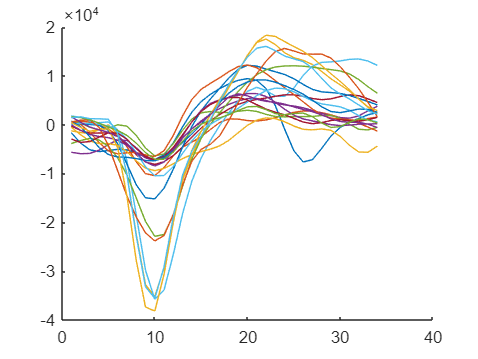

r = randi([0 3636],1,20);

hold on

for i = 1:length(r)
    plot(spike_data(r(i),:));
end

hold off

#### Question B

In order to choose different types of peaks, variation is needed to distinguish between these peaks; for example, one would not be able to distinguish between different types of peaks if the waveforms were all similar, so instead, we must take the time point with the most variation. Thus, the time point with the highest standard deviation will help us, which means that we are looking for the peak in a graph of the standard deviation of the waveforms at each time point. This time point in the graph is at 10 units.

Below is the plot of the standard deviation across time points.

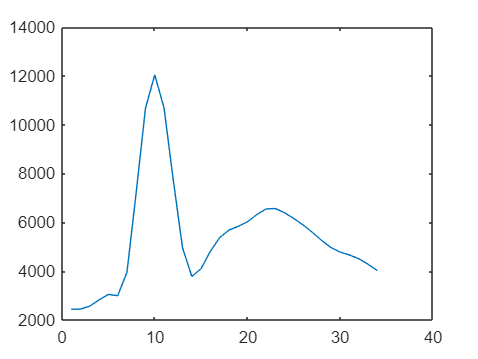

plot(std(spike_data));

#### Question C

Below is the plot of the covariance matrix for the spike data.

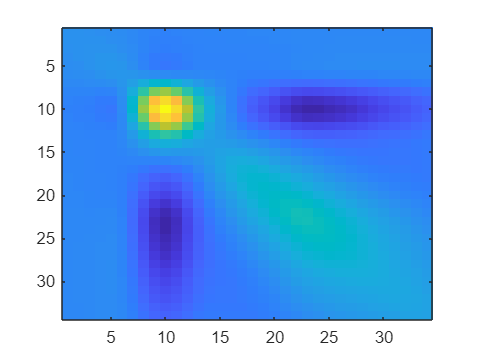

C = cov(spike_data);
imagesc(C);

#### Question D

Eigenvalues give us the explained variance of the PCA components, and each eigenvalue corresponds to an eigenvector that is a direction in which we orient the data. A larger eigenvalue for a principal component means that we can account for more of the variation within the data. We thus see that after 10 modes, most of the data can be explained. However, it is not very clear if there is an obvious number of modes to choose from, only that most of the variation in the data can be accounted for after 10 modes.

Below is the plot of the eigenvalue spectrum across the modes.

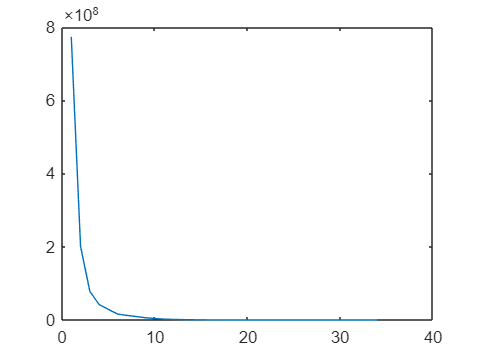

[eigenvectors,projections,eigenvalues] = pca(spike_data);
plot(eigenvalues);

#### Question E

The parts of the eigenvectors tell us the weight of the different time points on our data. 

For our eigenvector in blue, it seems that there is a peak at 10 units, meaning that the time point at 10 contributes most to the direction in which this eigenvector is oriented. This corresponds to our previous plot of the waveforms over time, as it seems like at time point 10 there seems to be dramatic, large troughs which may contribute to the data overall. 

For our eigenvector in orange, it seems that there is a peak at 20 units, meaning that the time point at 20 contributes most to the direction in which this eigenvector is oriented. This corresponds to our previous plot of waveforms over time, as it seems like at time point 20 there seems to be dramatic peaks in the waveforms which may contribute to the data overall.

Below is the plot of the first two eigenvectors from PCA.

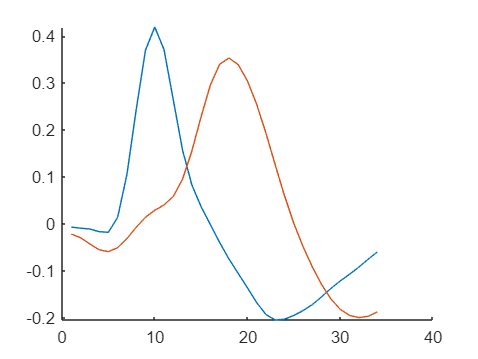

figure();

hold on

plot(eigenvectors(:,1));
plot(eigenvectors(:,2));

hold off

#### Question F

Below is the plot of the data’s projections onto the first two eigenvectors against each other. 

The scatterplot shows that the projection values congregate in two distinct areas, meaning that the waveforms can be separated so that there are two clusters of similar activity. Thus, it looks like there are two neurons. 

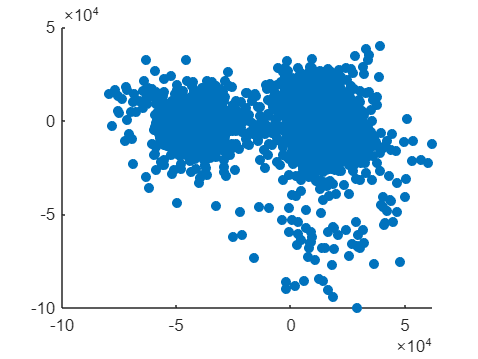

scatter(projections(:,1), projections(:,2), 'filled');

## Part 3

#### Question A

Below is the the plot of the the covariance matrix of the shuffled matrix.

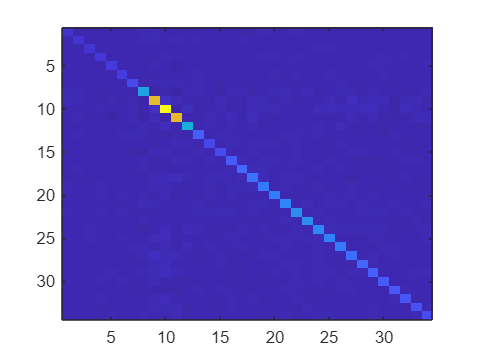

spike_data2 = zeros(3636, 34);

for i = 1:length(spike_data(1,:))
spike_data2(:,i) = spike_data(randperm(length(spike_data(:,1))),i);
end

C2 = cov(spike_data2);
imagesc(C2);

#### Question B

I did not expect this shape, because it seems like the only points of importance are on the diagonal, and the non-diagonals have much lesser covariances and are closer to zero. I expected that if we simply randomly shuffled, we would get a similar covariance matrix to the previous questions. However, it makes sense that the covariances seem closer to zero everywhere except for the diagonals because it means that the row values in each column are not correlated with the others in different columns. Since we shuffled by column, the resulting columns would no longer be correlated across a row or waveform.

#### Question C

Once we have subtracted the diagonal, we are left with off-diagonal values where some are positive and others negative, and not zero. However, they seem to fluctuate around zero. This is because we have subtracted from the off-diagonals the covariance values that are highest, so everything will in turn be smaller or negative. For negative values, this means that before the subtraction, there was a small correlation between the spike values, but after subtraction, there is now an inverse correlation. For slightly positive values, this means that there was a high correlation that has now been lowered. This makes sense because while we have gotten rid of most temporal patterns, some relationships (even noise) still remain.

Below is the plot of the covariance matrix with the subtracted diagonals.

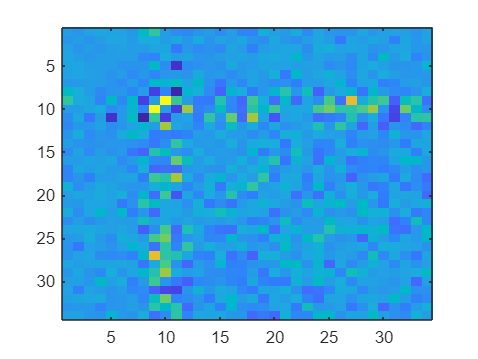

C3 = C2 - diag(diag(C2));
imagesc(C3);

#### Question D

Below is the plot of the eigenvalues of the shuffled(blue) and non-shuffled(orange) PCA.

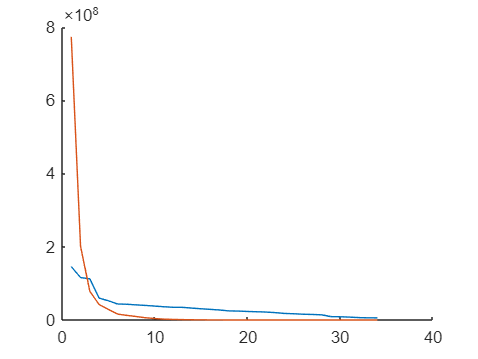

[eigenvectors2,projections2,eigenvalues2] = pca(spike_data2);

figure();
hold on
plot(eigenvalues2);
plot(eigenvalues);
hold off

#### Question E

Based on the previous plot, one can say there are around or at least 2-3 modes that are significant. In the unshuffled data, almost all the variance in the data can be accounted for by 2-3 modes. In the shuffled data, the amount of variance we can account for in the data tapers off after 3 modes. Additionally, the eigenvalues intersect at 2-3 dimensions. We can consider the shuffled data to be a sort of "null" or "control", where the eigenvalues of the shuffled data correspond to how much of the variance is accounted for when there is just noise.  Thus, for the unshuffled data, we must look at what is above the eigenvalue curve of the shuffled data to see how much variance is accounted for that isn't just attributable to noise. 

Thus, there are around 2-3 modes that are significant.